# Lab - MATLAB Review 1 

**Topics: **Vector indexing | Plotting | Manipulating the axis | Creating labels with special characters and data from code

## Projectiles

**1) Create a matrix for the initial values recreating the table:**

     Angle (in degrees) |   15 |  30 | 60

     Velocity (in m/s)     |   28 |  15 | 23

     Height (in m)          |     7 |  10 |   0

data = [15,30,60;28,15,23;7,10,0];

**2) Get values of x from 0 to 70 meters every 5 meters**

x=0:5:70;

**3) Add a new row with angles in radians since we need it for the formula**

 data(4,:) = data(1,:).*pi./180;

**4) Define g**

g = 9.81;

**5) Calculate height **$y=\tan \left(\theta_0 \right)x-\frac{g}{2v_0^2 \;\;\cos^2 {\;\theta }_0 }x^2 +y_0$ 

each row will contain heights for one set of conditions

y1= tan(data(4,1)).*x-((g/(2*(data(2,1)^2)*(cos(data(4,1))^2)))*(x.^2))+ data(3,1);
y2= tan(data(4,2)).*x-((g/(2*(data(2,2)^2)*(cos(data(4,2))^2)))*(x.^2))+ data(3,2);
y3= tan(data(4,3)).*x-((g/(2*(data(2,3)^2)*(cos(data(4,3))^2)))*(x.^2))+ data(3,3);


**6) Plot the three trajectories.  **

The 1st should be a red dotted line, the 2nd should be a black dashed line and the 3rd should be a blue dash-dot line.

plot(x,y1,"r:", x,y2,"k--",x,y3,"b-.")
xlabel = 'distance[m]'

xlabel = 'distance[m]'

ylabel = 'height [m]'

ylabel = 'height [m]'

title = 'Trajectories of Objects'

title = 'Trajectories of Objects'

**7) Adjust the axis so that the lower bound of the y axis is at 0 meters**

axis([0,60,0,25]);

**8) Show the initial values in the legend  (e.g.)  **$\theta_0 =?\;\deg ,y_0 =?\;m,v_0 =?\;\frac{m}{s}$

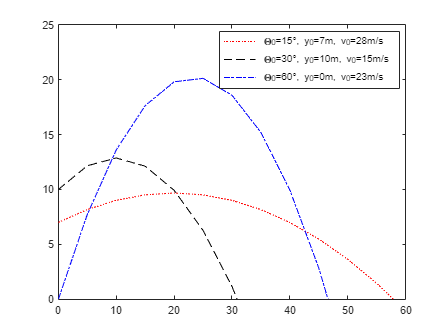

legend([' \Theta_0=',num2str(data(1,1)),'°, y_0=',num2str(data(3,1)),'m, v_0=',num2str(data(2,1)),'m/s'],[' \Theta_0=',num2str(data(1,2)),'°, y_0=',num2str(data(3,2)),'m, v_0=',num2str(data(2,2)),'m/s'],[' \Theta_0=',num2str(data(1,3)),'°, y_0=',num2str(data(3,3)),'m, v_0=',num2str(data(2,3)),'m/s'],'location','best')